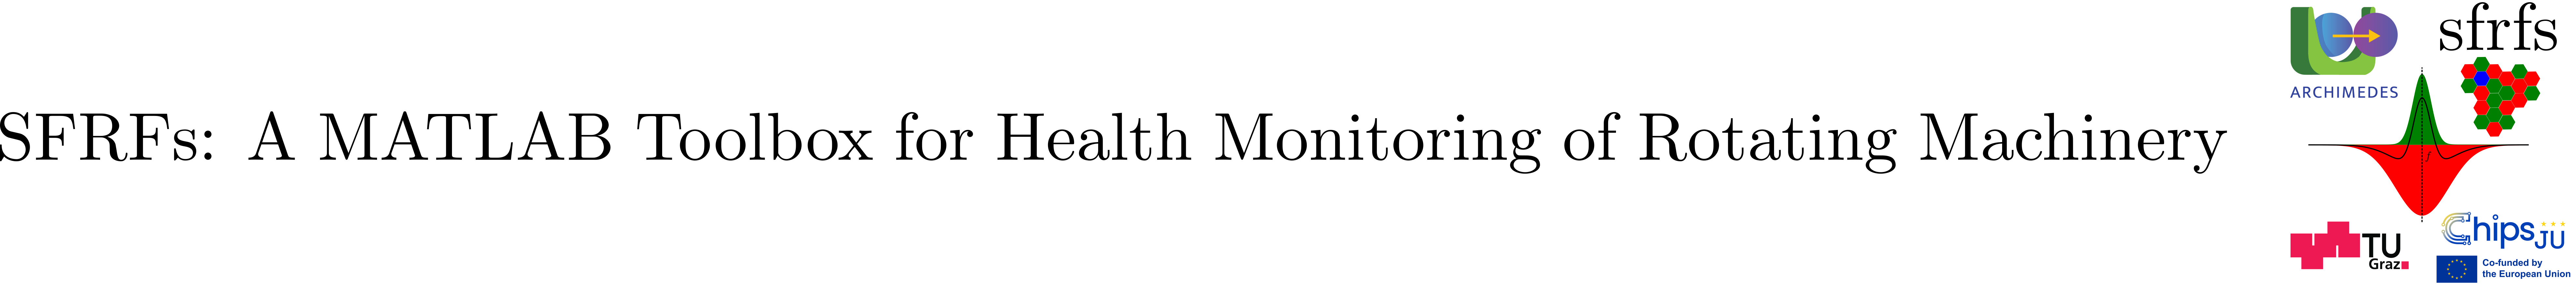

# LiftedHarmonicResponseCompute

## Summary

`LiftedHarmonicResponseCompute` is a handle class that computes harmonic-indexed center and surround spectral responses for Spectral Fault Receptive Fields (SFRFs). It applies precomputed harmonic masks to spectral data and evaluates user-supplied receptive-field response functions (RFRFs), preserving the individual responses associated with each harmonic.

**Key features:**

- Operates on a `LiftedHarmonicGainFunctions` instance containing precomputed harmonic-indexed center and surround masks.

- Processes spectral data from a user-specified column of a MATLAB table.

- Applies center and surround masks independently for each harmonic.

- Supports custom RFRFs through either a directly supplied function or a mask-dependent response-function binder.

- Preserves the historical SFRFs FFT-length amplitude-scaling convention before evaluating the response functions.

- Produces structured center and surround response matrices, together with harmonic indices and center frequencies.

The class provides a computational realization of harmonic-resolved spectral probe responses, corresponding to the Spectral Probe Family Response [SPFR] concept in the formal SFRFs framework [2].

## Description

`LiftedHarmonicResponseCompute` computes harmonic-resolved spectral responses for Spectral Fault Receptive Fields (SFRFs) using precomputed center and surround masks supplied by a `LiftedHarmonicGainFunctions` instance. It processes spectral observations stored in a MATLAB table and evaluates receptive-field response functions (RFRFs) independently for each harmonic.

For each harmonic, the class applies the corresponding center and surround masks to the input spectra and scales the resulting spectra by the number of supplied spectral bins, following the historical SFRFs FFT-length amplitude convention. The masked and scaled spectra are then passed to the configured response functions.

Response evaluation can be specified through a single user-defined RFRF, applied separately to both center and surround spectra, or through a response-function binder that constructs individual RFRFs using the corresponding masks. Exactly one of these two mechanisms must be supplied. When a binder is used, masks are passed to it for normalization or parameterization; mask application itself is performed by this class.

The resulting structure contains separate center and surround response matrices, with rows corresponding to spectral observations and columns corresponding to harmonic indices. Harmonic indices and center frequencies are retained as metadata. The class does not compute center-surround contrast or aggregate responses across harmonics.

This class provides a computational realization of harmonic-indexed Spectral Probe Family Responses [SPFR] within the formal SFRFs framework [2].

**See also:** [`LiftedHarmonicGainFunctions`](matlab:open('./LiftedHarmonicGainFunctions.mlx')), [`ReceptiveFieldResponseFunctions`](matlab:open('./ReceptiveFieldResponseFunctions.mlx')), [`SFRFsCompute`](matlab:open('./SFRFsCompute.mlx')), [`ParametersSnapshot`](matlab:open('./ParametersSnapshot.mlx'))

### Public properties

### Constructor

#### LiftedHarmonicResponseCompute

Constructs a harmonic-resolved spectral response computation object using snapshot parameters and a preconfigured `LiftedHarmonicGainFunctions` instance.

The constructor stores references to the supplied objects. The harmonic masks must be computed before invoking `compute()`.

**Syntax**

`lhrc = LiftedHarmonicResponseCompute( ...`

`    snapshotParameters=sp, ...`

`    liftedGainFunctions=lhgf);`

**Parameters**

**Output**

Returns a `LiftedHarmonicResponseCompute` handle object. The constructor initializes the computation configuration but does not evaluate spectral responses. Call `compute()` with spectral observations and an RFRF specification to obtain the harmonic-resolved responses.

## Public methods

#### compute

Computes harmonic-indexed center and surround spectral responses from a collection of spectral observations.

For each harmonic, the method applies its precomputed center and surround masks to the input spectra, performs the historical SFRFs FFT-length amplitude scaling, and evaluates the selected receptive-field response functions (RFRFs) independently.

The RFRFs can be supplied directly through `receptiveFieldResponseFunction` or constructed individually through `receptiveFieldResponseBinder`. Exactly one of these arguments must be provided.

**Syntax**

Using a directly supplied response function:

`responses = lhrc.compute( ...`

`    memberTable=memberTable, ...`

`    spectralColumn="Spectrum", ...`

`    receptiveFieldResponseFunction=rf);`

Alternatively, using a mask-dependent response binder:

`responses = lhrc.compute( ...`

`    memberTable=memberTable, ...`

`    spectralColumn="Spectrum", ...`

`    receptiveFieldResponseBinder=binder);`

**Parameters**

The spectral data must be compatible with the precomputed frequency domain. The implementation accepts a numeric spectral array, a cell containing a spectral array, or a cell array of individual spectral vectors.

The selected RFRFs must accept the masked spectral array and frequency domain as arguments and return one response value per observation.

**Output**

Returns a structure `responses` containing:

For N spectral observations and H selected harmonics, `Center` and `Surround` have dimensions (N x H).

The method preserves individual harmonic responses without computing center-surround contrast or aggregating across harmonics.

## Example

This example illustrates the computation of harmonic-indexed center and surround spectral responses. We first construct the harmonic gain functions, then apply them to a collection of synthetic spectral observations using a mask-dependent receptive-field response function.

### Harmonic-indexed response computation

We configure three harmonics of a characteristic frequency of 100 Hz. The center and surround masks follow the same parameterization used in the `LiftedHarmonicGainFunctions` example.

% Define snapshot parameters
sp = ParametersSnapshot( ...
    samplingFrequency = 1024, ...
    duration = 1, ...
    stride = 1);

% Define SFRF parameters
sharedParams = SFRFsParameters.buildSFRFsParameters( ...
    order = 0, ...
    numSidebands = 0, ...
    numHarmonics = 3, ...
    centerMask = SuperGaussianMaskParameters( ...
    alpha = 2, ...
    beta = 8), ...
    surroundMask = SuperGaussianMaskParameters( ...
    alpha = 6, ...
    beta = 2), ...
    inhibitionFactor = 0.9);

sfrfsParams = SFRFsParametersRollingBearings( ...
    SameForAllFaultTypes = sharedParams);

ft = SFRFsParametersRollingBearings.OUTER_RACE_FAULT_TYPE_NAME;
sel = OperatingConditionSelection(speed = 35, load = 12);

% Construct and compute harmonic gain functions
lhgf = LiftedHarmonicGainFunctions( ...
    snapshotParameters = sp, ...
    sfrfsParameters = sfrfsParams, ...
    faultType = ft, ...
    selection = sel, ...
    characteristicFrequencyHz = 100, ...
    harmonicIndices = [1; 2; 3]);

lhgf.compute();

Next, we construct synthetic spectra containing peaks at the selected harmonic frequencies. The spectrum of each observation is stored as a column vector, and the observations are collected in a MATLAB table.

We use the documented `maskedMeanAbs` binder, which normalizes the response by the effective spectral mask area. The masks are applied and FFT-scaled by `LiftedHarmonicResponseCompute` before evaluation.

% Frequency domain and synthetic spectral observations
f = lhgf.frequencyDomain;
peak = @(fc) exp(-0.5 .* ((f - fc) ./ 1.5).^2);

X = [ ...
    1.0 .* peak(100) + 0.6 .* peak(200) + 0.3 .* peak(300), ...
    0.6 .* peak(100) + 1.0 .* peak(200) + 0.8 .* peak(300), ...
    0.3 .* peak(100) + 0.5 .* peak(200) + 1.0 .* peak(300)];

memberTable = table({X}, 'VariableNames', {'Spectrum'});

% Configure response function
binder = ReceptiveFieldResponseFunctions.maskedMeanAbs();

% Compute harmonic-indexed responses
lhrc = LiftedHarmonicResponseCompute( ...
    snapshotParameters = sp, ...
    liftedGainFunctions = lhgf);

responses = lhrc.compute( ...
    memberTable = memberTable, ...
    spectralColumn = "Spectrum", ...
    receptiveFieldResponseBinder = binder);

disp(responses.Center);

   1.0e-03 *

    0.7591    0.4554    0.2277
    0.4554    0.7591    0.6073
    0.2277    0.3795    0.7591



disp(responses.Surround);

   1.0e-03 *

    0.3255    0.1953    0.0977
    0.1953    0.3255    0.2604
    0.0977    0.1628    0.3255



The resulting `Center` and `Surround` matrices each have dimensions 3 x 3, representing three observations and three harmonics. Both matrices preserve the same harmonic ordering.

### Visualizing the harmonic responses

We can compare the resulting center and surround response matrices directly. Rows represent spectral observations, while columns represent harmonic indices.

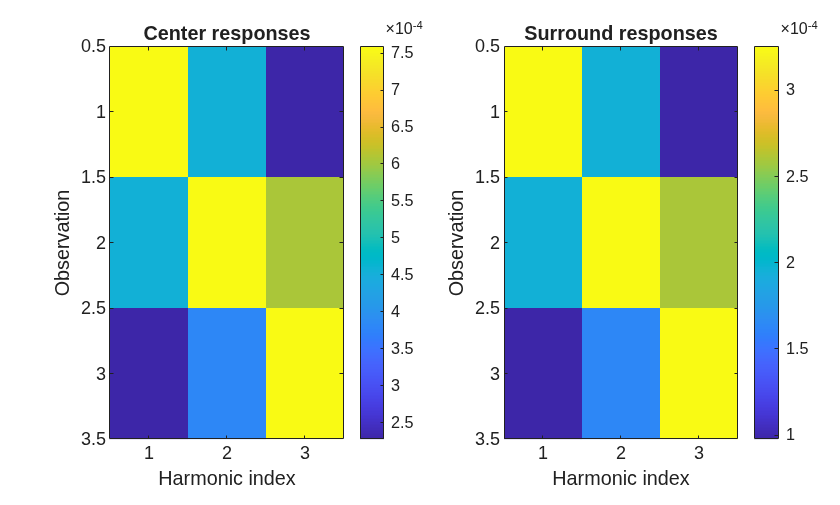

figure;

tiledlayout(1, 2);

nexttile;
imagesc(responses.Center);
colorbar;
title('Center responses');
xlabel('Harmonic index');
ylabel('Observation');
xticks(1:numel(responses.HarmonicIndex));
xticklabels(string(responses.HarmonicIndex));

nexttile;
imagesc(responses.Surround);
colorbar;
title('Surround responses');
xlabel('Harmonic index');
ylabel('Observation');
xticks(1:numel(responses.HarmonicIndex));
xticklabels(string(responses.HarmonicIndex));

## API documentation

### MATLAB help

The MATLAB `help` command displays the class documentation extracted from its source file.

help LiftedHarmonicResponseCompute

 LiftedHarmonicResponseCompute
 
  Applies lifted center/surround harmonic masks and evaluates injected
  RFRFs independently on the resulting center/surround spectra.
 
  Convention:
  This class owns the lifted-mask application and the historical SFRFs
  FFT-length amplitude scaling. RFRFs receive already masked and scaled
  spectra. If a receptiveFieldResponseBinder is supplied, masks are passed
  to the binder only for normalization or parameterization.

    Documentation for LiftedHarmonicResponseCompute



**MATLAB ****documentation**

The MATLAB `doc` command opens the corresponding documentation in the MATLAB Help Browser.

doc LiftedHarmonicResponseCompute

## Source code

The source code of this class can be found in [`LiftedHarmonicResponseCompute`](matlab:open('../../LiftedHarmonicResponseCompute.m')).

edit LiftedHarmonicResponseCompute

## Test

Unit testing for the class is implemented in [`TestLiftedHarmonicResponseCompute`](matlab:open('../../../tests/TestLiftedHarmonicResponseCompute.m')).

res = runtests('tests/TestLiftedHarmonicResponseCompute.m');

Running TestLiftedHarmonicResponseCompute
.......... .
Done TestLiftedHarmonicResponseCompute
__________



SFRFsTestUtil.printTestSummary(res, 80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestLiftedHarmonicResponseCompute/testResponseBinderIsApplied                    | Passed
TestLiftedHarmonicResponseCompute/testMissingRFRFSpecificationThrows             | Passed
TestLiftedHarmonicResponseCompute/testDoubleRFRFSpecificationThrows              | Passed
TestLiftedHarmonicResponseCompute/testValidConstruction                          | Passed
TestLiftedHarmonicResponseCompute/testComputeReturnsExpectedFields               | Passed
TestLiftedHarmonicResponseCompute/testResponseSizes                              | Passed
TestLiftedHarmonicResponseCompute/testIntegralAbsMatchesManualComputation        | Passed
TestLiftedHarmonicResponseCompute/testCustomRFRFIsInjected                       | Passed
TestLiftedHarmonicResponseCompute/testHarmonicMetadataIsPreserved                | Passed
TestLifted

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). *SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery*. Zenodo. [DOI: 10.5281/zenodo.17631784](https://doi.org/10.5281/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).

- [2] Stan Muñoz Gutiérrez and Franz Wotawa. *A Formal Framework for Spectral Fault Receptive Fields (with Examples for Bearing Health Monitoring).* Technical Report TR-SFRFs-v1.0.1, Institute of Software Engineering and Artificial Intelligence, Graz University of Technology, Graz, Austria (2026).